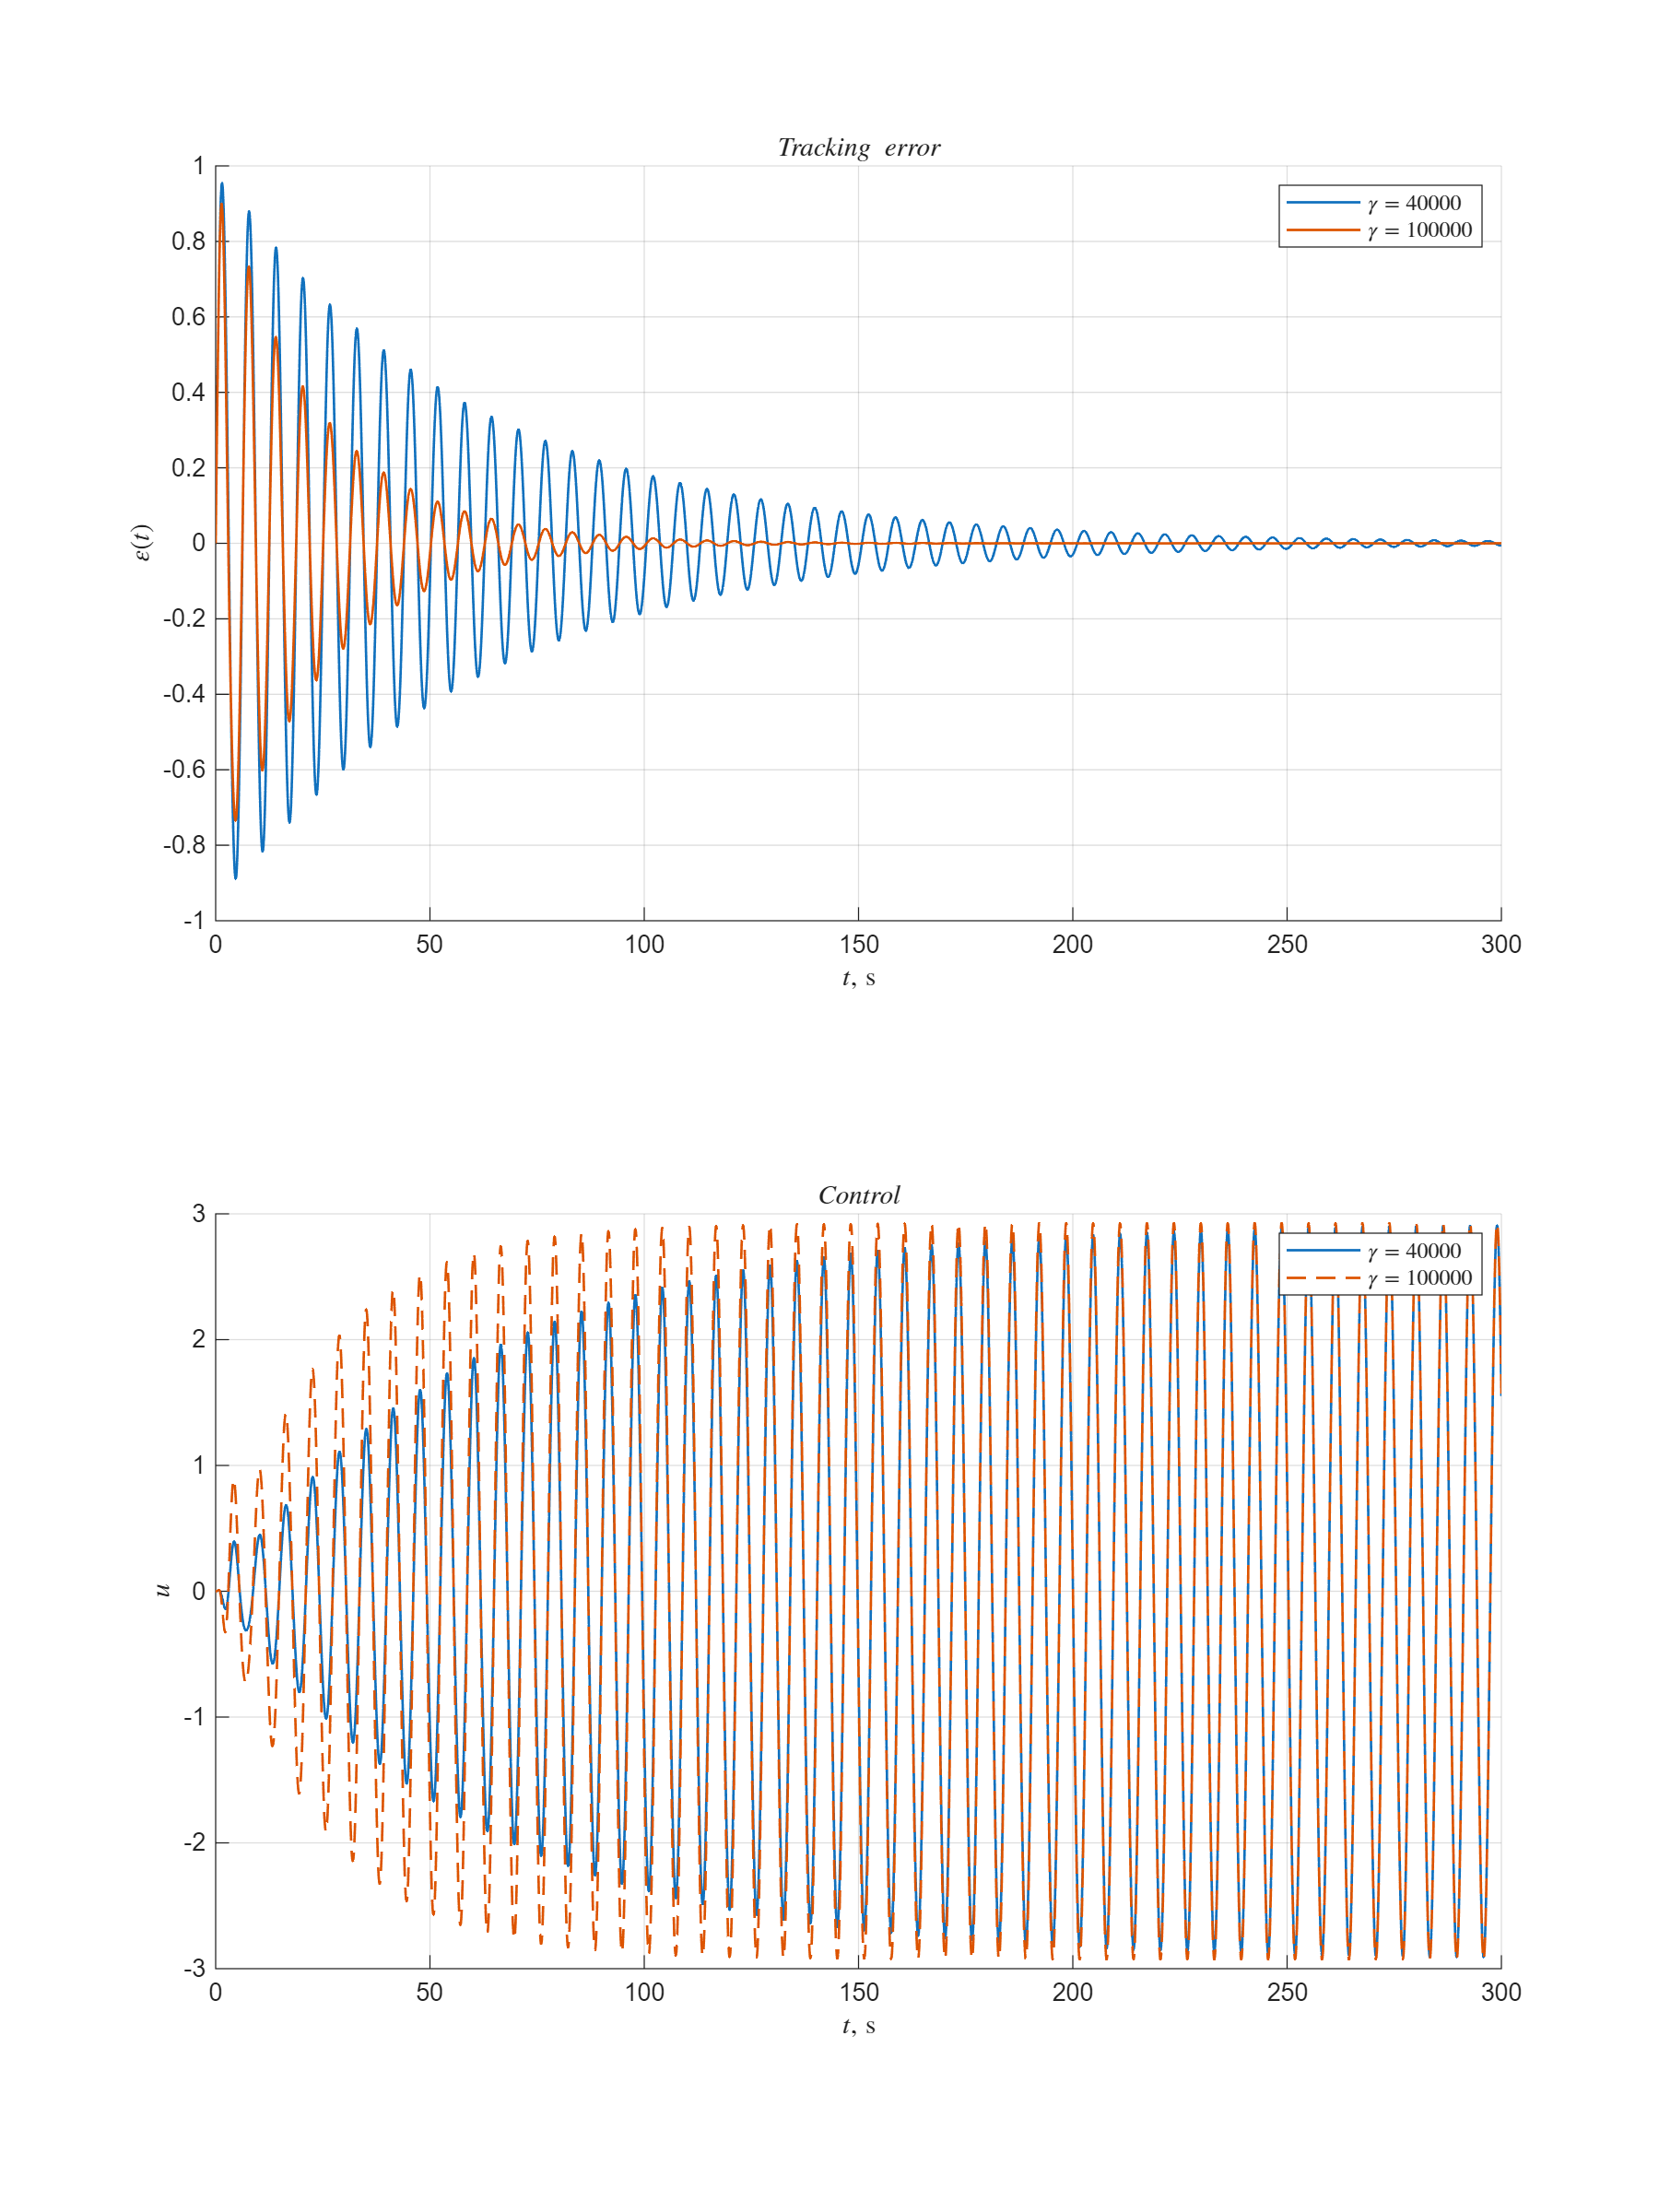

A = [3 1; 1 1];
b = [1; 2];
K = [434.225220821837 -178.650599773935];
AM = A - b*K;

kg1 = 0.8;
kg0 = 0.16;

numW = [1 1];
denW = [1 -trace(AM) det(AM)];

gamma1 = 40000;
gamma2 = 100000;
simtime = 300;

gamma = gamma1;
out = sim("lab12.slx", simtime);
eps1 = out.error.Data;
u1 = out.u.Data;
t1 = out.error.Time;

gamma = gamma2;
out = sim("lab12.slx", simtime);
eps2 = out.error.Data;
u2 = out.u.Data;
t2 = out.error.Time;

f = figure;
f.Position = [100 100 900 1200];

labels = { ...
    sprintf('$\\gamma=%g$', gamma1), ...
    sprintf('$\\gamma=%g$', gamma2)};
subplot(2,1,1);
hold on;
plot(t1, eps1, LineWidth=1);
plot(t2, eps2, LineWidth=1);
hold off;

legend(labels, Interpreter="latex");
grid on;
title("$Tracking\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$\varepsilon(t)$", Interpreter="latex");

subplot(2,1,2);
hold on;
plot(t1, u1, LineWidth=1);
plot(t2, u2, LineStyle="--", LineWidth=1);
hold off;

legend(labels, Interpreter="latex");
grid on;
title("$Control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");

folder = "C:/Users/Nickolay/Desktop/ITMO-courses/7_term/Adaptive_and_robust_control/lab12/tex/images/";
exportgraphics(f, fullfile(folder, "lab12.png"), Resolution=600);